# Квантовая криптография

#### Ослабленные лазерные импульсы

Решение проблемы приготовления однофотонных фоковскиих состояний - ослабление лазерных импульсов, поле которых находится в когерентном состоянии со средним числом фотонов N. Вероятность найти n фотонов в таком состоянии описывается распределением Пуассона

clear
digits(3)
syms N n 
P(n,N)=N^n/factorial(n)*exp(-N)

$$P(n, N) = \frac{N^{n}\,{\mathrm{e}}^{-N}}{n!}$$

N1=5;
n1=0.1;
vpa(P(N1,n1))

$$ans = 7.54e-8$$

Соответственно, вероятность того, что в непустом (n~=) импульсе содержится более одного фотона

$\begin{array}{l}
P\left(n>1|n>0,N\right)=\frac{1-P\left(0,N\right)-P\left(1,N\right)}{1-P\left(0,N\right)}=\\
=\frac{1-\left\lbrack \frac{N^0 e^{-N} }{0!}\right\rbrack -\frac{N^1 e^{-N} }{1!}}{\left\lbrack \frac{N^0 e^{-N} }{0!}\right\rbrack }=\frac{1-e^{-N} \left(1+N\right)}{1-e^{-N} }\approx \frac{N}{2}
\end{array}$                             (22)

Вероятность может быть сделана произвольно малой при уменьшении N. Однако в этом случае большинство импульсов окажется пустым! Действительно, при малых N


$$P\left(n=0\right)=\frac{N^0 }{0!}e^{-N} \to 1-N$$


Упрощенная временная развертка событий в КК представлена на рис.3

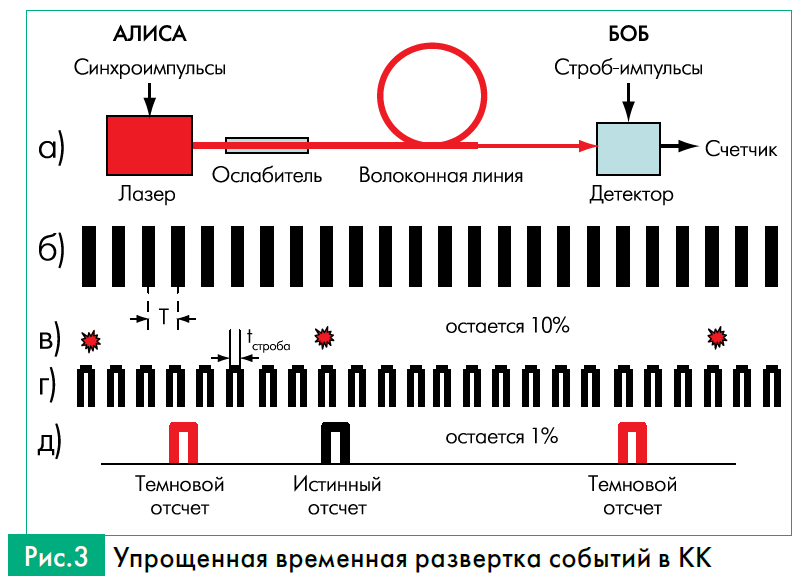

### Кодирование

#### Кодирование по поляризации

Основные состояния при кодировании по поляризации


$$|\updownarrow >\;=|V>$$



$$|\leftrightarrow >\;=|H>$$



$$|/>\;=\frac{1}{\sqrt{2}}\left\lbrace |H>+|V>\right\rbrace$$



$$\left|\;\backslash >\;=\frac{1}{\sqrt{2}}\left\lbrace \left|H>-\right|V>\right\rbrace \right.$$



$$|L>\;=\frac{1}{\sqrt{2}}\left\lbrace |H>+i|V>\right\rbrace$$



$$|R>\;=\frac{1}{\sqrt{2}}\left\lbrace |H>-i|V>\right\rbrace$$


Они соответствуют вертикальной, горизонтальной, диагональным и (право- и лево) циркулярным поляризациям однофотонных фоковских состояний.

#### Кодирование по фазе

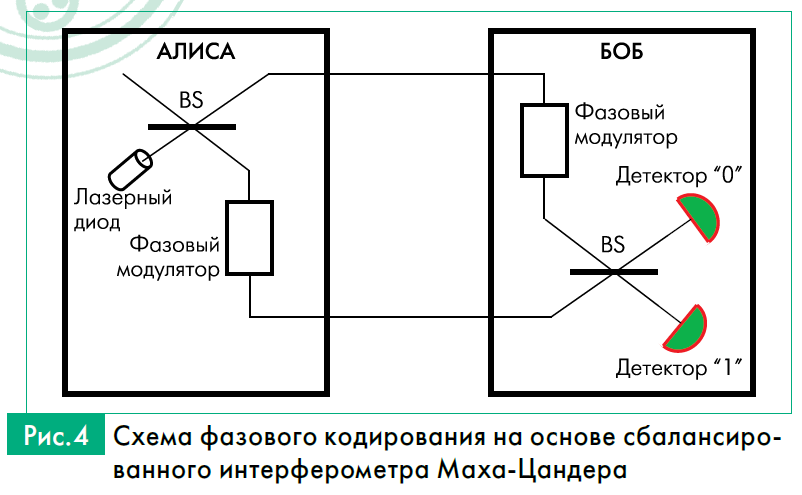

Такой споособ основан на использовании двухплечевого интерферометра Маха-Цандера (рис.4)

Интенсивность в выходной моде "0" станции Боба:


$$I_0 =\bar{I} \;{\mathrm{cos}}^2 \left(\frac{\phi_A -\phi_B +k\Delta L}{2}\right)$$


На практике удобнее использовать другую схему - два разбалансированных интерферометра Маха-Цандера (рис.5)

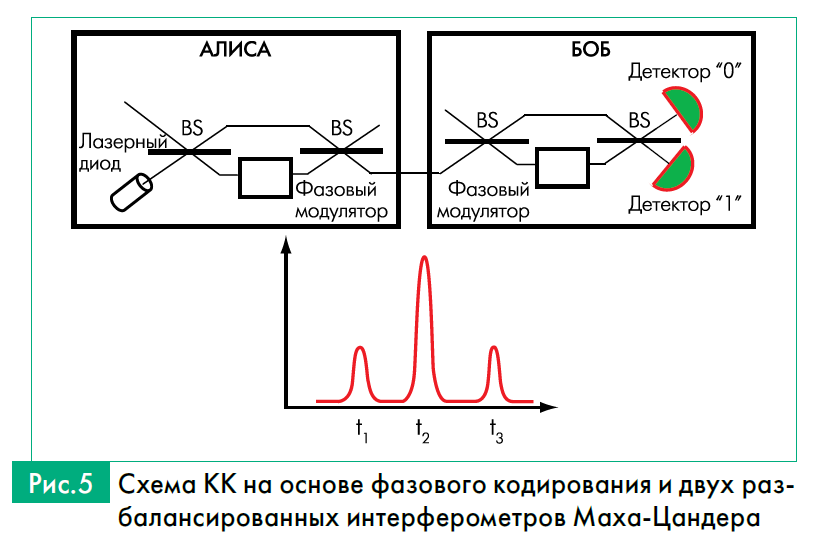

В протоколе BB84 используются два (или в общем случае три) взаимно несмещенных базисы, состоящих из пары ортногоноальных состояний. Такие базисы удовлетворяют условию


$$|<\psi_i |\varphi_i >|^2 =\frac{1}{D}$$


в то время как для состояний из одного базиса


$$<\psi_i |\psi_j \ge 0\;\;\left(i,j=1,2\right)$$
